% =========================================================================
% KÍSÉRLET 09: a durva GA konvergenciája
% =========================================================================
% MIT CSINÁL?
%   Ugyanazt a Fourier-GA-t futtatja le, mint a 02_ga_durva\g1_ga_durva
%   (ugyanaz a rács, költség, beállítások és seedek), de generációnként
%   elmenti a populáció állapotát. Így látszik, hogyan javul a megoldás a
%   generációk során, mikor áll le az egyes indítás, és mennyire térnek el
%   egymástól a független indítások.
%
%   A GA-lépés (ga_run_naplo, a szkript végén) soronként megegyezik a
%   kozos\lib\ga_run.m-mel, csak a naplózás került bele. Mivel a seedek is
%   ugyanazok (cfg.ga.seed + s - 1), az indítások végeredménye pontosan a fő
%   futásé. A szkript ezt a végén ellenőrzi az opt_osszesites.csv-vel.
%   A fő futás eredményeit nem írja felül, minden kimenet a kísérlet mappájába kerül.
%
%   Generációnként mentett adatok:
%     - a legjobb fitnesz eddig (ez csak csökkenhet, az elitizmus miatt);
%     - a populáció fitneszének mediánja és 25-75 %-os tartománya
%       (az átlag helyett, mert a büntetett egyedek fitnesze nagyságrendekkel
%       nagyobb, és az átlagot elvinné);
%     - a mutáció szórása a tartomány szélességéhez képest [%].
%   A fitnesz itt költség + büntetés (ga_fitness.m); büntetés nélküli
%   egyednél ez maga a költség, az Alap költsége 1.
%
% BEMENET:  01_racs\CAND2.csv (a fő futás rácsa),
%           02_ga_durva\eredmenyek_korlat\01_ga\opt_osszesites.csv (ellenőrzéshez)
% KIMENET (kiserletek\09_ga_konvergencia\eredmenyek\):
%   konvergencia.csv     indítás, generáció, legjobb fitnesz, javulás az
%                        Alaphoz [%], populáció medián, 25 %, 75 %, mutáció szórása [%]
%   inditasok.csv        indításonként: seed, generációk száma a leállásig,
%                        végső költség, javulás [%]
%   c_1_konvergencia.png a legjobb megoldás javulása a generációk függvényében,
%                        mind a 8 indításra
%   c_2_populacio.png    a legjobb indítás populációja: legjobb, medián,
%                        25-75 %-os sáv, és a mutáció szórásának csökkenése
% FUTÁSIDŐ: ugyanannyi, mint a g1_ga_durva (több perc).
% =========================================================================
clear; clc; close all;
%% 0. ÚTVONALAK
% A projekt gyökere az a mappa, amelyben a kozos\config.m van. A futó Live
% Script helyét a matlab.desktop.editor.getActiveFilename adja meg; ha ez
% nem érhető el, a MATLAB aktuális mappájából indulunk. Innen legfeljebb
% három szintet lépünk felfelé, amíg a kozos\config.m meg nem lesz. Így a
% teljes mappa bárhová másolható, abszolút elérési utat nem kell átírni.
gyoker = '';
try, gyoker = fileparts(matlab.desktop.editor.getActiveFilename); catch, end
jeloltek = {gyoker, pwd};
for c = 1:numel(jeloltek)
    gyoker = jeloltek{c};
    for i = 1:3
        if isempty(gyoker) || isfile(fullfile(gyoker, 'kozos', 'config.m')), break; end
        gyoker = fileparts(gyoker);
    end
    if ~isempty(gyoker) && isfile(fullfile(gyoker, 'kozos', 'config.m')), break; end
end
assert(~isempty(gyoker) && isfile(fullfile(gyoker, 'kozos', 'config.m')), ...
    'Nem található a kozos\config.m. Állítsd a MATLAB aktuális mappáját a szkript mappájára.');
addpath(fullfile(gyoker, 'kozos'), fullfile(gyoker, 'kozos', 'lib'));
% Ugyanaz a beállítás, mint a g1-nél (a CAND2.zip-et is kicsomagolja, ha kell).
cfg = beallit();
out = fullfile(cfg.path.kis, '09_ga_konvergencia', 'eredmenyek');
if ~exist(out, 'dir'), mkdir(out); end

%% 1. Rács, Alap, költség (ugyanaz, mint a g1-ben)
fprintf('Beolvasás: %s\n', cfg.file.cand_coarse);

Beolvasás: C:\Users\dozsa\OneDrive\Desktop\ATMENETIBME\5_felev\tdk\01_v10\01_racs\CAND2.csv


G  = cand_beolvas(cfg.file.cand_coarse, cfg);
Op = deriv_ops(G.key_ang, cfg.coarse.n_eval, cfg.geom.radius);
Dn = koltseg_osztok(negyzetosszeg(Op, G.alap_q), cfg);
J_alap = koltseg(negyzetosszeg(Op, G.alap_q), Dn, cfg);

% A keresési tér és a célfüggvény, pontosan úgy, mint a g1-ben.
H  = cfg.coarse.harmonics;
ub = repmat([cfg.ga.bound_a0; repmat(cfg.ga.bound_harm, 2*H, 1)], 3, 1);
lb = -ub;
fit = @(P) ga_fitness(P, G, Op, Dn, cfg, H);

%% 2. GA-indítások naplózással
ns = cfg.ga.n_starts;
best_J = zeros(1, ns);  ngen = zeros(1, ns);
N = cell(1, ns);
for s = 1:ns
    seed_rng(cfg.ga.seed + s - 1);
    [~, best_J(s), N{s}] = ga_run_naplo(fit, lb, ub, cfg.ga);
    ngen(s) = numel(N{s}.best) - 1;          % a 0. generáció a kezdő populáció
    fprintf('  indítás %d (seed %d): %3d generáció, költség %.4f (%+.2f%% vs Alap)\n', ...
        s, cfg.ga.seed + s - 1, ngen(s), best_J(s), 100*(best_J(s)/J_alap - 1));
end

  indítás 1 (seed 1): 300 generáció, költség 0.5395 (-46.05% vs Alap)
  indítás 2 (seed 2): 235 generáció, költség 0.5415 (-45.85% vs Alap)
  indítás 3 (seed 3): 141 generáció, költség 0.5458 (-45.42% vs Alap)
  indítás 4 (seed 4): 300 generáció, költség 0.5387 (-46.13% vs Alap)
  indítás 5 (seed 5): 151 generáció, költség 0.5432 (-45.68% vs Alap)
  indítás 6 (seed 6): 300 generáció, költség 0.5395 (-46.05% vs Alap)
  indítás 7 (seed 7): 300 generáció, költség 0.5401 (-45.99% vs Alap)
  indítás 8 (seed 8): 147 generáció, költség 0.5457 (-45.43% vs Alap)



%% 3. Ellenőrzés: ugyanaz-e a végeredmény, mint a fő futásban
% Az opt_osszesites.csv minden megtartott megoldásánál szerepel, melyik
% indításból jött (inditas oszlop) és mennyi lett a költsége.
if exist(cfg.file.opt_sum, 'file')
    [T, hT] = csv_olvas(cfg.file.opt_sum);
    ci = strcmpi(hT, 'inditas');  ck = strcmpi(hT, 'koltseg');
    T = T(T(:,1) > 0, :);
    for r = 1:size(T, 1)
        s = T(r, ci);
        assert(abs(best_J(s) - T(r, ck)) < 1e-5, ...
            'A %d. indítás költsége (%.6f) eltér a fő futásétól (%.6f).', s, best_J(s), T(r, ck));
    end
    fprintf('Ellenőrzés: a megtartott megoldások költsége megegyezik a fő futáséval.\n');
end

Ellenőrzés: a megtartott megoldások költsége megegyezik a fő futáséval.


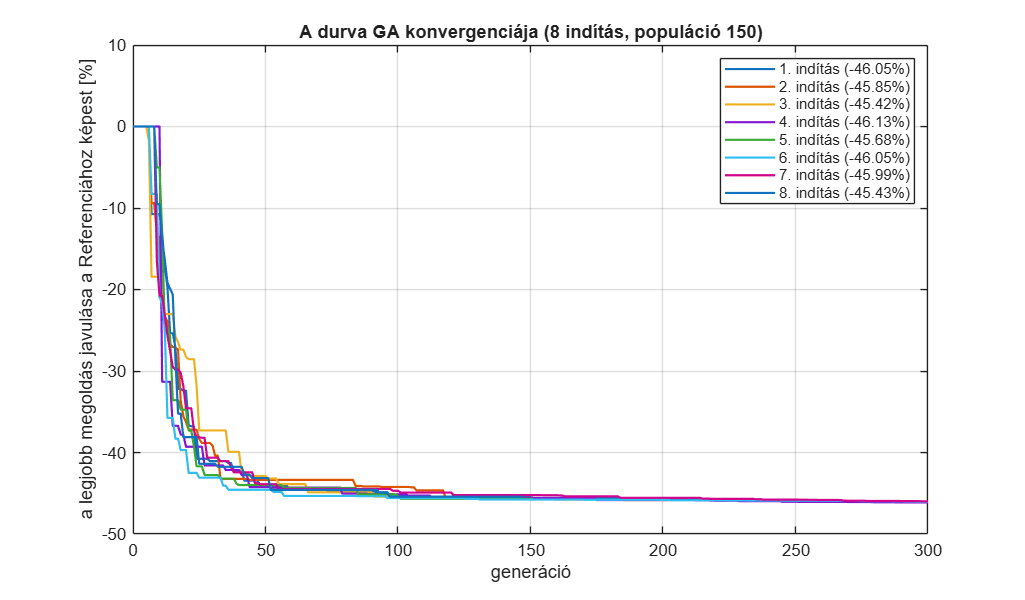


%% 4. Kimenet: CSV
M = [];
for s = 1:ns
    g = (0:ngen(s))';
    M = [M; s*ones(size(g)), g, N{s}.best, 100*(N{s}.best/J_alap - 1), ...
         N{s}.med, N{s}.q25, N{s}.q75, N{s}.sig]; %#ok<AGROW>
end
csv_iras(fullfile(out, 'konvergencia.csv'), ...
    {'inditas','generacio','legjobb','legjobb_vs_alap_pct','median','q25','q75','mutacio_szoras_pct'}, M);
csv_iras(fullfile(out, 'inditasok.csv'), {'inditas','seed','generaciok','koltseg','vs_alap_pct'}, ...
    [(1:ns)', cfg.ga.seed + (0:ns-1)', ngen', best_J', 100*(best_J'/J_alap - 1)]);

%% 5. Ábrák
% c_1: a legjobb megoldás javulása a generációk függvényében, indításonként.
% A görbe vége az a generáció, ahol az indítás leállt (50 generáció javulás nélkül).
figure('Color', 'w', 'Position', [100 100 820 480]); hold on; grid on; box on;
for s = 1:ns
    plot(0:ngen(s), 100*(N{s}.best/J_alap - 1), 'LineWidth', 1.3, ...
        'DisplayName', sprintf('%d. indítás (%.2f%%)', s, 100*(best_J(s)/J_alap - 1)));
end
xlabel('generáció'); ylabel('a legjobb megoldás javulása a Referenciához képest [%]');
title(sprintf('A durva GA konvergenciája (%d indítás, populáció %d)', ns, cfg.ga.pop_size));
legend('Location', 'northeast');
saveas(gcf, fullfile(out, 'c_1_konvergencia.png'));


% c_2: a legjobb indítás populációja. A bal tengelyen a legjobb egyed és a
% populáció mediánja, a 25-75 %-os sávval (fitnesz, az Alap = 1), a jobb
% tengelyen a mutáció szórása a tartomány szélességének százalékában.
[~, sb] = min(best_J);
g = 0:ngen(sb);
figure('Color', 'w', 'Position', [100 100 820 480]);
yyaxis left; hold on; grid on; box on;
fill([g fliplr(g)], [N{sb}.q25' fliplr(N{sb}.q75')], [0.75 0.85 1], ...
    'EdgeColor', 'none', 'DisplayName', 'populáció 25-75 %');
plot(g, N{sb}.med,  '-',  'LineWidth', 1.3, 'DisplayName', 'populáció mediánja');
plot(g, N{sb}.best, '-',  'LineWidth', 2.0, 'DisplayName', 'legjobb egyed');
plot([0 g(end)], [1 1], 'k--', 'DisplayName', 'Referencia (= 1)');
set(gca, 'YScale', 'log');
ylabel('fitnesz (célfüggvény értéke + büntetés)');
yyaxis right;
plot(g, N{sb}.sig, ':', 'LineWidth', 1.5, 'DisplayName', 'mutáció szórása');
ylabel('mutáció szórása a tartományhoz [%]');
xlabel('generáció');
title(sprintf('A %d. indítás populációja', sb));
legend('Location', 'northeast');
saveas(gcf, fullfile(out, 'c_2_populacio.png'));


%% Helyi függvény: a ga_run.m naplózással
function [xbest, fbest, N] = ga_run_naplo(fit, lb, ub, o)
% GA_RUN_NAPLO  Soronként a kozos\lib\ga_run.m, generációnkénti naplóval.
%   A véletlenszámok hívási sorrendje megegyezik a ga_run.m-mel, ezért
%   azonos seeddel azonos eredményt ad. N mezői (oszlopvektorok, az első
%   elem a kezdő populáció):
%     best  a legjobb fitnesz eddig      med, q25, q75  a populáció fitneszének
%     sig   a mutáció szórása [%]        mediánja és kvartilisei
np = numel(lb);  N_pop = o.pop_size;
X = repmat(lb, 1, N_pop) + repmat(ub - lb, 1, N_pop) .* rand(np, N_pop);
X(:, 1) = 0;
F = fit(X);
[fbest, ib] = min(F);  xbest = X(:, ib);  stall = 0;
N = naplo([], F, fbest, 16);
for g = 1:o.max_gen
    [~, srt] = sort(F);
    E = X(:, srt(1:o.elite));
    nk = N_pop - o.elite;
    A = X(:, tour(F, nk, o.tour_k));
    B = X(:, tour(F, nk, o.tour_k));
    lo = min(A, B);  d = max(A, B) - lo;
    C = (lo - 0.3*d) + (1.6*d) .* rand(np, nk);
    sig = (0.15*(1 - g/o.max_gen) + 0.01) * (ub - lb);
    m = rand(np, nk) < o.p_mut;
    C = C + m .* (repmat(sig, 1, nk) .* randn(np, nk));
    C = min(max(C, repmat(lb, 1, nk)), repmat(ub, 1, nk));
    X = [E C];
    F = [F(srt(1:o.elite)) fit(C)];
    [fg, ib] = min(F);
    if fg < fbest - 1e-9
        fbest = fg; xbest = X(:, ib); stall = 0;
    else
        stall = stall + 1;
    end
    N = naplo(N, F, fbest, 100*(0.15*(1 - g/o.max_gen) + 0.01));
    if stall >= o.stall_gen, break; end
end
end

function N = naplo(N, F, fbest, sig_pct)
% Egy generáció adatainak hozzáfűzése a naplóhoz.
q = sort(F(:));  n = numel(q);
kv = @(p) q(max(1, min(n, round(p*(n-1)) + 1)));
if isempty(N), N = struct('best', [], 'med', [], 'q25', [], 'q75', [], 'sig', []); end
N.best(end+1, 1) = fbest;
N.med(end+1, 1)  = kv(0.50);
N.q25(end+1, 1)  = kv(0.25);
N.q75(end+1, 1)  = kv(0.75);
N.sig(end+1, 1)  = sig_pct;
end

function idx = tour(F, n, k)
% Versenyszelekció, mint a ga_run.m-ben.
c = randi(numel(F), k, n);
[~, w] = min(F(c), [], 1);
idx = c(sub2ind(size(c), w, 1:n));
end
